%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% AUDIO_DIGIT_ANALYSIS_META3.M
%
% Script for Audio Digit Analysis - Meta 3
% Tasks:
% 16) Load data structure from previous meta (finalAudioData.mat).
% 17) Considering the best extracted characteristics from the time and frequency signals
%     in the points 8 and 14, respectively, apply a classifier to automate the identification
%     of the digits through the characteristics.
% 18) Compare the atributed digits to each audio through the classifier used in the point 17
%     with the original digits and define the accuracy percentage of the classifier
%     (number of correctly classified digits / total number of digits * 100).
% 19) Compare the three different windows, applying them in time intervals
% 20)  Update the data structure file (finalAudioData.mat).
%
% Authors: [Teodoro Marques, Bernardo Direito]
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; close all; clc;

## INITIAL PARAMETERS

participantID = 40;             % Unique participant identifier
digitNumbers = 0:9;             % Digits from 0 to 9

## STAGE 16: LOAD DATA STRUCTURE FROM PREVIOUS META

load('finalAudioData.mat', 'metadataTable');
disp('Data structure loaded from finalAudioData.mat');

Data structure loaded from finalAudioData.mat


## STAGE 17: CLASSIFIER: Using random forest

% Combine the best features from time (Stage 8) and frequency (Stage 14)
% Assuming the best features are already identified:
% Time features: TotalEnergy, StandardDeviation
% Frequency features: SpecMaxAmp, SpecCentroid

% Extract features and labels obtained in stages 8 and 14
features = [metadataTable.TotalEnergy, metadataTable.StandardDeviation, ...
    metadataTable.SpecMaxAmp, metadataTable.SpecCentroid];
labels = metadataTable.DigitValue; % True digit labels

% Remove rows with missing or invalid data
validIndices = all(~isnan(features), 2) & ~isnan(labels);
features = features(validIndices, :);
labels = labels(validIndices);

% Split data into training (80%) and testing (20%) sets
cv = cvpartition(labels, 'HoldOut', 0.2);
trainFeatures = features(training(cv), :);
trainLabels = labels(training(cv));
testFeatures = features(test(cv), :);
testLabels = labels(test(cv));

% Train the random forest classifier using the fitcensemble function
% with Bagging method
randomForestModel = fitcensemble(trainFeatures, trainLabels, ...
    'Method', 'Bag', 'NumLearningCycles', 100, 'Learners', 'Tree');

% Predict the test set using the predict function
predictedLabels = predict(randomForestModel, testFeatures);

% Save the trained model for future use
save('randomForestModel.mat', 'randomForestModel');

## STAGE 18: COMPARE CLASSIFIER RESULTS WITH ORIGINAL DIGITS

% Display a comparison between predicted and true labels
comparisonTable = table(testLabels, predictedLabels, ...
    'VariableNames', {'TrueLabels', 'PredictedLabels'});
disp('Comparison of True and Predicted Labels:');

Comparison of True and Predicted Labels:


disp(comparisonTable);

    TrueLabels    PredictedLabels
    __________    _______________

        0                0       
        0                9       
        0                5       
        0                2       
        0                5       
        0                0       
        0                0       
        0                0       
        0                0       
        0                2       
        1                7       
        1                9       
        1                5       
        1                1       
        1                7       
        1                1       
        1                1       
        1                1       
        1                1       
        1                9       
        2                0       
        2                2       
        2                9       
        2                0       
        2                0       
        2    


% Calculate accuracy
accuracyPercentage = sum(predictedLabels == testLabels) / length(testLabels) * 100;
fprintf('Random Forest Classifier Accuracy: %.2f%%\n', accuracyPercentage);

Random Forest Classifier Accuracy: 55.00%



% Confusion matrix
confMatrix = confusionmat(testLabels, predictedLabels);
disp('Confusion Matrix:');

Confusion Matrix:


disp(confMatrix);

     5     0     2     0     0     2     0     0     0     1
     0     5     0     0     0     1     0     2     0     2
     3     1     4     0     0     1     0     0     0     1
     0     0     1     4     0     2     2     1     0     0
     1     0     0     0     8     1     0     0     0     0
     0     1     0     2     0     1     0     3     3     0
     0     0     0     0     0     0    10     0     0     0
     0     3     1     2     0     0     0     4     0     0
     0     0     1     1     0     0     0     0     8     0
     2     0     0     0     0     1     0     1     0     6



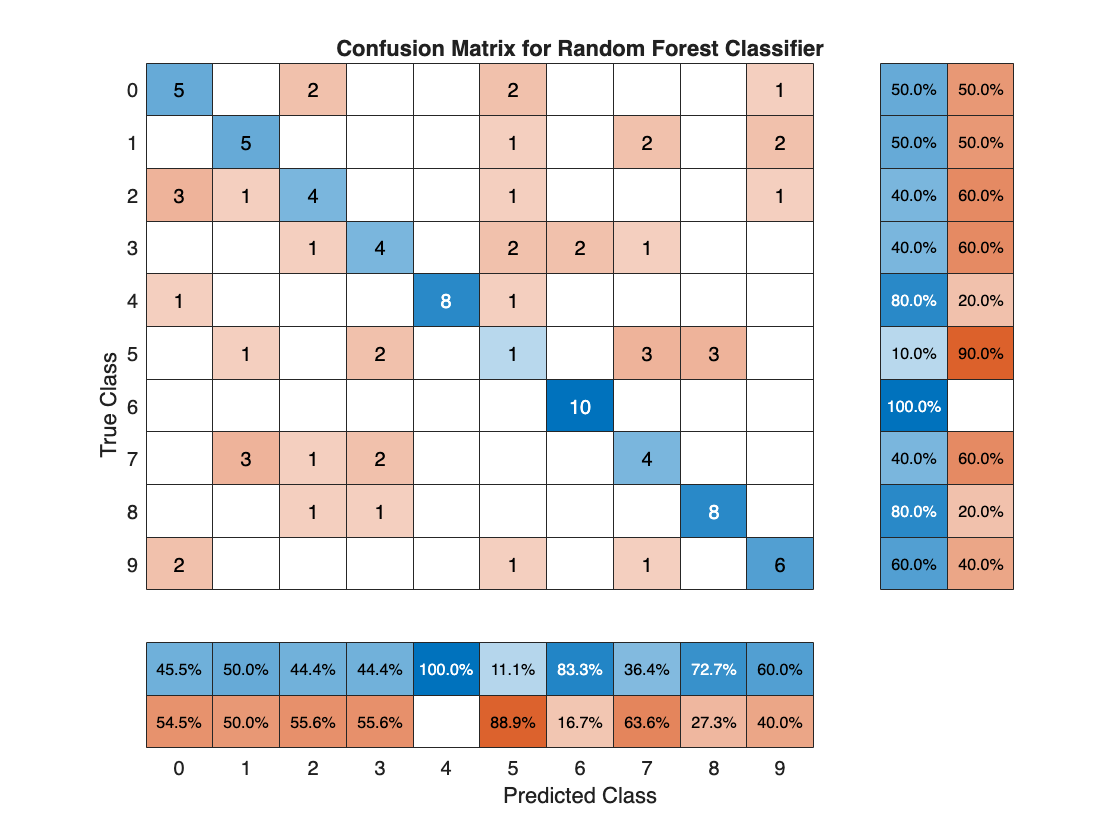


% Plot the confusion matrix
figure('Name', 'Confusion Matrix', 'NumberTitle', 'off');
confusionchart(confMatrix, digitNumbers, ...
    'Title', 'Confusion Matrix for Random Forest Classifier', ...
    'RowSummary', 'row-normalized', 'ColumnSummary', 'column-normalized');

## STAGE 19: COMPARE THREE DIFFERENT WINDOWS

% Define the three different window types
windowTypes = {'rectwin', 'hamming', 'hann'};
windowNames = {'Rectangular', 'Hamming', 'Hann'};

% Preallocate accuracy storage for each window type
windowAccuracies = zeros(length(windowTypes), 1);

% Loop through each window type
for w = 1:length(windowTypes)
    % Apply the window to the features (assuming features are time-domain signals)
    windowFunction = str2func(windowTypes{w});
    windowedFeatures = features .* windowFunction(size(features, 1));

    % Split data into training (80%) and testing (20%) sets
    % do this for each iteration
    cv = cvpartition(labels, 'HoldOut', 0.2);
    trainFeatures = windowedFeatures(training(cv), :);
    trainLabels = labels(training(cv));
    testFeatures = windowedFeatures(test(cv), :);
    testLabels = labels(test(cv));

    % Train the random forest classifier
    randomForestModel = fitcensemble(trainFeatures, trainLabels, ...
        'Method', 'Bag', 'NumLearningCycles', 100, 'Learners', 'Tree');

    % Predict the test set
    predictedLabels = predict(randomForestModel, testFeatures);

    % Calculate accuracy for this window type
    windowAccuracies(w) = sum(predictedLabels == testLabels) / length(testLabels) * 100;
    fprintf('Accuracy with %s window: %.2f%%\n', windowNames{w}, windowAccuracies(w));

    % Display a summary of accuracies for all window types
    fprintf('%s Window: %.2f%%\n', windowNames{w}, windowAccuracies(w));
end

Accuracy with Rectangular window: 54.00%


Rectangular Window: 54.00%


Accuracy with Hamming window: 77.00%


Hamming Window: 77.00%


Accuracy with Hann window: 74.00%


Hann Window: 74.00%


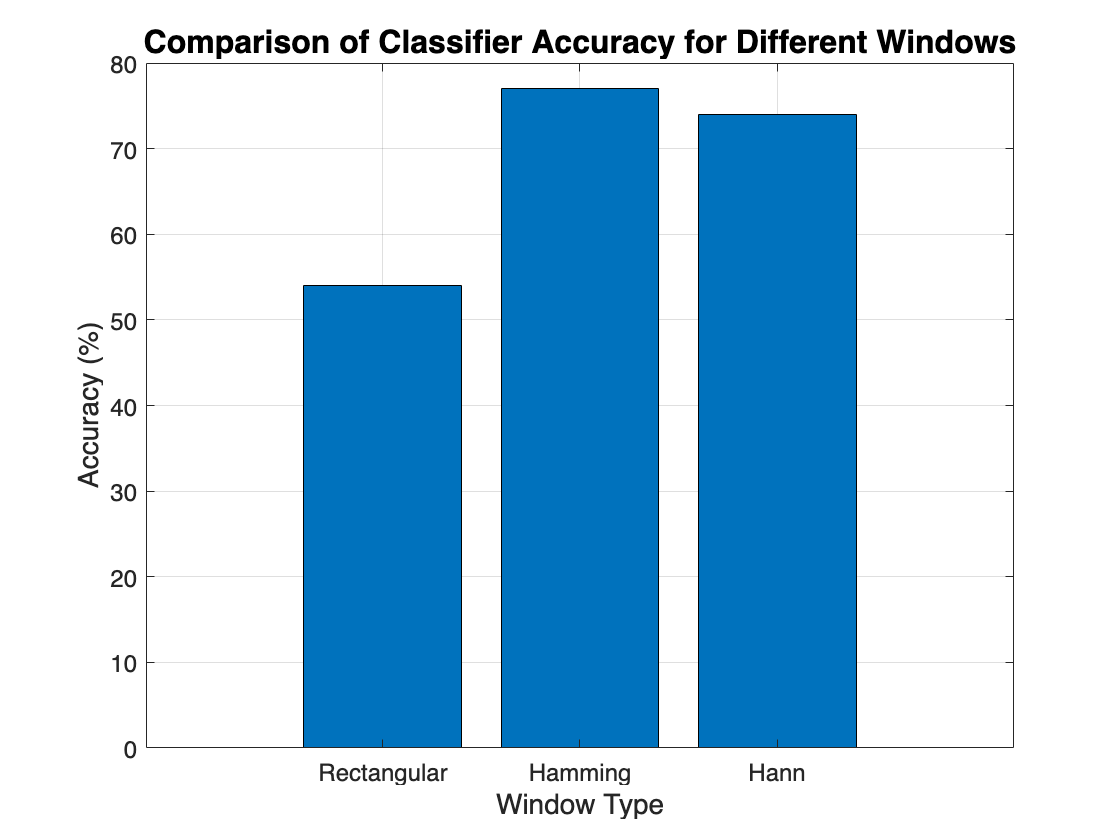


% Plot the accuracies for comparison
figure('Name', 'Window Comparison', 'NumberTitle', 'off');
bar(windowAccuracies);
set(gca, 'XTickLabel', windowNames, 'FontSize', 12);
xlabel('Window Type', 'FontSize', 14);
ylabel('Accuracy (%)', 'FontSize', 14);
title('Comparison of Classifier Accuracy for Different Windows', 'FontSize', 16);
grid on;

## STAGE 20: UPDATE DATA STRUCTURE FILE

Update the metadata table with the new features and accuracies

summaryTable = table(windowNames', windowAccuracies, ...
                     'VariableNames',{'Window','Accuracy'});
% Save the updated data structure
save('finalAudioData.mat','metadataTable','summaryTable');
disp('finalAudioData.mat updated with complete data structure.');

finalAudioData.mat updated with complete data structure.
